clear; clc; close all
%% Radar parameters
c = physconst('LightSpeed'); %speed of light
BW = 50e6; %bandwidth
f0 = 3000e6; % carrier frequency
numADC = 361; % # of adc samples
numChirps = 256; % # of chirps per frame

numCPI = 10;
T = 10e-3; % PRI 
PRF = 1/T;
F = numADC/T; % sampling frequency
dt = 1/F; % sampling interval
slope = BW/T;
lambda = c/f0;



N = numChirps*numADC*numCPI; % total # of adc samples
t = linspace(0,T*numChirps*numCPI,N); % time axis, one frame

% size(0:dt:dt*numADC-dt)
t_onePulse=0:dt:dt*numADC-dt;
Vmax = lambda/(T*4); % Max Unamb velocity m/s



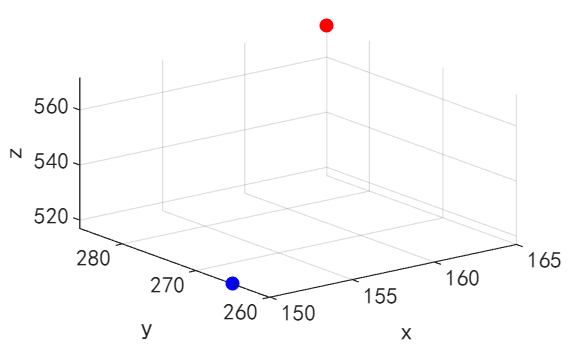


%% Targets

r1_radial = 660;
tar1_theta = 30;
tar1_phi=60;
r1_x = cosd(tar1_phi)*sind(tar1_theta)*r1_radial;
r1_y = sind(tar1_phi)*sind(tar1_theta)*r1_radial;
r1_z = cosd(tar1_theta)*r1_radial;

v1_radial = 0.001; % velocity 1
v1_x = cosd(tar1_phi)*cosd(tar1_theta)*v1_radial;
v1_y = sind(tar1_phi)*cosd(tar1_theta)*v1_radial;
v1_z = sind(tar1_theta)*v1_radial;
r1 = [r1_x r1_y r1_z];


tar1_loc = zeros(length(t),3);
tar1_loc(:,1) = r1(1) + v1_x*t;
tar1_loc(:,2) = r1(2) + v1_y*t;
tar1_loc(:,3) = r1(3) + v1_z*t;

scatter3(tar1_loc(1,1),tar1_loc(1,2),tar1_loc(1,3),'r','filled')
hold on

r2_radial = 600;
tar2_theta = 30.5;
tar2_phi = 60.5;
r2_x = cosd(tar2_phi)*sind(tar2_theta)*r2_radial;
r2_y = sind(tar2_phi)*sind(tar2_theta)*r2_radial;
r2_z = cosd(tar2_theta)*r2_radial;

v2_radial = 0.1; % velocity 1
v2_x = cosd(tar2_phi)*sind(tar2_theta)*v2_radial;
v2_y = sind(tar2_phi)*sind(tar2_theta)*v2_radial;
v2_z = cosd(tar2_theta)*v2_radial;
r2 = [r2_x r2_y r2_z];


tar2_loc = zeros(length(t),3);
tar2_loc(:,1) = r2(1) + v2_x*t;
tar2_loc(:,2) = r2(2) + v2_y*t;
tar2_loc(:,3) = r2(3) + v2_z*t;

scatter3(tar2_loc(1,1),tar2_loc(1,2),tar2_loc(1,3),'blue','filled')
xlabel('x');
ylabel('y');
zlabel('z');
hold off

numTX = 1;
numRX = 8;

% N_L=floor(2*f0/BW);
% N_L=(mod(N_L, 2) == 0)*(N_L-1)+(mod(N_L, 2) == 1)*(N_L); % 扩展的虚拟阵列
N_L=1;
N_num=2*(N_L-1)+1

N_num = 1

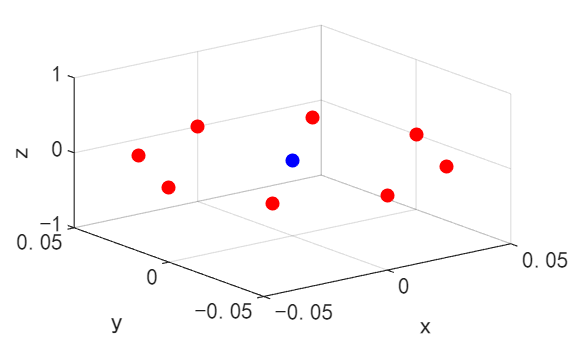


% 均匀圆阵参数
R_tx = 0; % 发射阵列半径（根据实际调整）
R_rx = 0.05; % 接收阵列半径

tr_vel=2*pi/N_num/numRX/T;
% tr_vel=0;

% 生成发射天线位置（均匀分布在圆上）
theta_tx = linspace(0, 2*pi, numTX+1); theta_tx(end) = [];
tx_loc = cell(numTX);
tx_loc_t= cell(numTX);
for i = 1:numTX
    tx_loc{i} = [R_tx*cos(theta_tx(i)), R_tx*sin(theta_tx(i)), 0];

    tx_loc_t{i}=zeros(length(t),3);
    tx_loc_t{i}(:,1)=R_tx*cos(theta_tx(i)+tr_vel*t);
    tx_loc_t{i}(:,2)=R_tx*sin(theta_tx(i)+tr_vel*t);
    tx_loc_t{i}(:,3)=0;

    scatter3(tx_loc{i}(1),tx_loc{i}(2),tx_loc{i}(3),'b','filled')
    hold on
end

% 生成接收天线位置
theta_rx = linspace(0, 2*pi, numRX+1); theta_rx(end) = [];
rx_loc = cell(numRX,1);
rx_loc_t = cell(numRX,1);
for i = 1:numRX
    rx_loc{i} = [R_rx*cos(theta_rx(i)), R_rx*sin(theta_rx(i)), 0];

    rx_loc_t{i}=zeros(length(t),3);
    rx_loc_t{i}(:,1)=R_rx*cos(theta_rx(i)+tr_vel*t);
    rx_loc_t{i}(:,2)=R_rx*sin(theta_rx(i)+tr_vel*t);
    rx_loc_t{i}(:,3)=0;

    scatter3(rx_loc{i}(1),rx_loc{i}(2),rx_loc{i}(3),'r','filled')
    hold on
end
xlabel('x');
ylabel('y');
zlabel('z');
hold off


theta_circle = linspace(0, 2*pi, numRX*(2*(N_L-1)+1)+1); theta_circle(end) = [];
circle_loc=cell(numRX*(2*(N_L-1)+1),1);
for i = 1:numRX*(2*(N_L-1)+1)
    circle_loc{i} = [R_rx*cos(theta_circle(i)), R_rx*sin(theta_circle(i)), 0];
end


P1 = rx_loc{1,1};
P2 = r1;


% 计算两点之间的距离
d = sqrt((P2(1) - P1(1))^2 + (P2(2) - P1(2))^2 + (P2(3) - P1(3))^2);

% 计算仰角
theta = acos((P2(3) - P1(3)) / d); % 仰角，单位为弧度

% 计算方向角
phi = atan2(P2(2) - P1(2), P2(1) - P1(1)); % 方向角，单位为弧度

% 如果需要，可以将弧度转换为度
theta_deg = rad2deg(theta);
phi_deg = rad2deg(phi);

% 输出结果
fprintf('仰角 (弧度): %.4f\n', theta);

仰角 (弧度): 0.5236


fprintf('方向角 (弧度): %.4f\n', phi);

方向角 (弧度): 1.0473


fprintf('仰角 (度): %.4f\n', theta_deg);

仰角 (度): 29.9981


fprintf('方向角 (度): %.4f\n', phi_deg);

方向角 (度): 60.0075


%% TX

delays_tar1 = cell(numTX,numRX);
delays_tar2 = cell(numTX,numRX);

for i = 1:numTX
    for j = 1:numRX
        delays_tar1{i,j} = (vecnorm(tar1_loc-rx_loc_t{j},2,2) ...
                        +vecnorm(tar1_loc-tx_loc_t{i},2,2))/c; 
        delays_tar2{i,j} = (vecnorm(tar2_loc-rx_loc_t{j},2,2) ...
                        +vecnorm(tar2_loc-tx_loc_t{i},2,2))/c;
    end
end



%% Complex signal
phase = @(tx,fx) 2*pi*(fx.*tx+slope/2*tx.^2); % transmitted
snr=50;
mixed = cell(numTX,numRX);

for i = 1:numTX
    for j = 1:numRX
        disp(['Processing Channel: ' num2str(j) '/' num2str(numRX)]);
        for k = 1:numChirps*numCPI
            phase_t = phase(t_onePulse,f0);
            phase_1 = phase(t_onePulse-delays_tar1{i,j}((k-1)*numADC+1:k*numADC)',f0); % received
            phase_2 = phase(t_onePulse-delays_tar2{i,j}((k-1)*numADC+1:k*numADC)',f0);
            
            signal_t((k-1)*numADC+1:k*numADC) = exp(1j*phase_t);
            signal_1((k-1)*numADC+1:k*numADC) = exp(1j*(phase_t - phase_1));
            signal_2((k-1)*numADC+1:k*numADC) = exp(1j*(phase_t - phase_2));
        end
        % mixed{i,j} =awgn(signal_1+signal_2,snr,'measured');
        
        mixed{i,j} = signal_1+signal_2;
    end
end

Processing Channel: 1/8
Processing Channel: 2/8
Processing Channel: 3/8
Processing Channel: 4/8
Processing Channel: 5/8
Processing Channel: 6/8
Processing Channel: 7/8
Processing Channel: 8/8


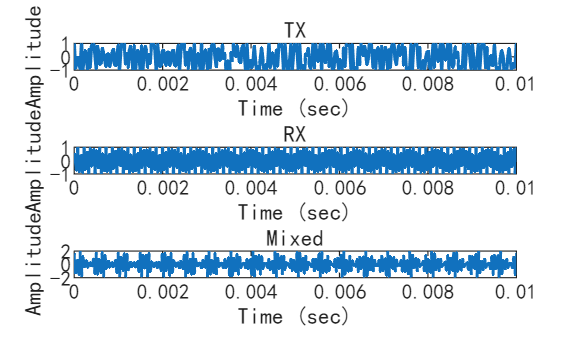


figure
subplot(3,1,1)
p1 = plot(t, real(signal_t));
title('TX')
xlim([0 0.1e-1])
xlabel('Time (sec)');
ylabel('Amplitude');
subplot(3,1,2)
p2 = plot(t, real(signal_1));
title('RX')
xlim([0 0.1e-1])
xlabel('Time (sec)');
ylabel('Amplitude');
subplot(3,1,3)
p3 = plot(t,real(mixed{1,1,1}));
title('Mixed')
xlim([0 0.1e-1])
xlabel('Time (sec)');
ylabel('Amplitude');

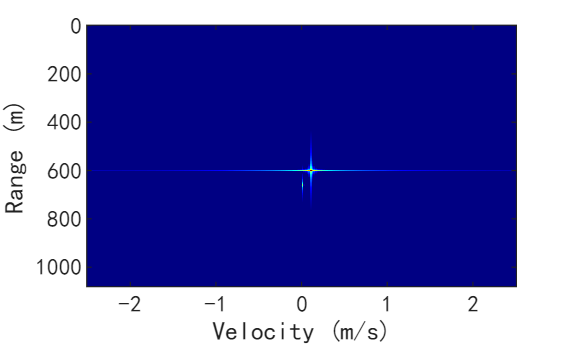


%% Post processing - 2-D FFT
% size(cat(3,mixed{:}))



RDC = reshape(cat(3,mixed{:}),numADC,numChirps*numCPI,numRX*numTX); % radar data cube

RDC_plus=zeros(numADC,(numChirps-2*(N_L-1))*numCPI,numRX*numTX*(2*(N_L-1)+1));
    
for i = 1:numCPI
    for j = 1:numChirps-2*(N_L-1)
        for k = 1:numRX*numTX
            RDC_plus(:,j+(i-1)*(numChirps-2*(N_L-1)),N_L+(k-1)*(2*(N_L-1)+1))=RDC(:,j+(N_L-1)+(i-1)*(numChirps-2*(N_L-1)),k);
            for l =1:N_L-1                
                RDC_plus(:,j+(i-1)*(numChirps-2*(N_L-1)),N_L+l+(k-1)*(2*(N_L-1)+1))=RDC(:,j+(N_L-1)+l+(i-1)*(numChirps-2*(N_L-1)),k);
                RDC_plus(:,j+(i-1)*(numChirps-2*(N_L-1)),N_L-l+(k-1)*(2*(N_L-1)+1))=RDC(:,j+(N_L-1)-l+(i-1)*(numChirps-2*(N_L-1)),k);
            end
        end
    end
end
%扩展后仍需要根据新旋转后的位置对通道进行修正
RDC_plus_rot=zeros(numADC,(numChirps-2*(N_L-1))*numCPI,numRX*numTX*(2*(N_L-1)+1));
if tr_vel==0
       RDC_plus_rot=RDC_plus;
       delta_phi = 0; % 计算固定的方位角偏移量
else
    for i = 1:numChirps-2*(N_L-1)
        RDC_plus_rot(:,i,:)=circshift(RDC_plus(:,i,:), (i-1), 3);
    end
    delta_phi = 360/N_num/numRX; % 计算固定的方位角偏移量
end



numChirps_new=numChirps-2*(N_L-1);

DFmax = 1/2*PRF; % = Vmax/(c/f0/2); % Max Unamb Dopp Freq
dR = c/(2*BW); % range resol
Rmax = F*c/(2*slope); % TI's MIMO Radar doc
Rmax2 = c/2/PRF; % lecture 2.3
dV = lambda/(2*numChirps*T); % velocity resol, lambda/(2*framePeriod)

N_Dopp = numChirps_new; % length of doppler FFT
N_range = numADC; % length of range FFT
N_azimuth = numRX*numTX*(2*(N_L-1)+1);
R = 0:dR:Rmax-dR; % range axis
V = linspace(-Vmax, Vmax, numChirps_new); % Velocity axis
% 
ang_phi = -180:0.1:180; % angle axis
ang_theta=0:0.1:90;


% ang_phi = 50:0.01:70++360/N_num/numRX; % angle axis
% ang_theta=40:0.01:60;


RDMs = zeros(numADC,numChirps_new,numRX*numTX*(2*(N_L-1)+1),numCPI);
for i = 1:numCPI
    RD_frame = RDC_plus_rot(:,(i-1)*numChirps_new+1:i*numChirps_new,:);
    RDMs(:,:,:,i) = fftshift(fft2(RD_frame,N_range,N_Dopp),2);
    % RDMs(:,:,:,i) = RD_frame;
end




figure
imagesc(V,R,20*log10(abs(RDMs(:,:,1,1))/max(max(abs(RDMs(:,:,1,1))))));
colormap(jet(256))
% set(gca,'YDir','normal')
clim = get(gca,'clim');
caxis([clim(1)/2 0])
xlabel('Velocity (m/s)');
ylabel('Range (m)');

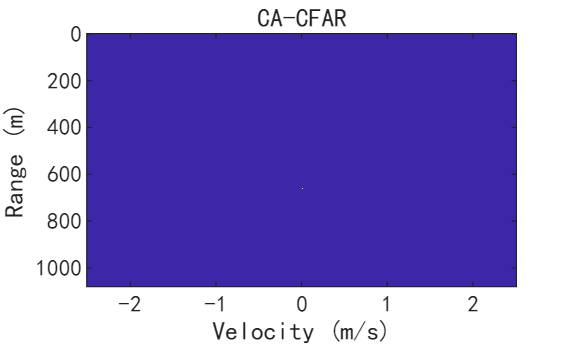


%% CA-CFAR

numGuard = 2; % # of guard cells
numTrain = numGuard*2; % # of training cells
P_fa = 1e-5; % desired false alarm rate 
SNR_OFFSET = -1; % dB
RDM_dB = 10*log10(abs(RDMs(:,:,1,1))/max(max(abs(RDMs(:,:,1,1)))));

[RDM_mask, cfar_ranges, cfar_dopps, K] = ca_cfar(RDM_dB, numGuard, numTrain, P_fa, SNR_OFFSET);
cfar_ranges_real=(cfar_ranges-1)*3;
figure
h=imagesc(V,R,RDM_mask);
xlabel('Velocity (m/s)')
ylabel('Range (m)')
title('CA-CFAR')

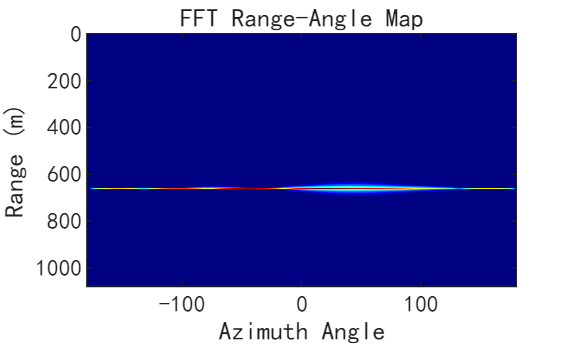


%% Angle Estimation - FFT

rangeFFT = fft(RDC_plus_rot(:,1:numChirps_new,:),numADC);

angleFFT = fftshift(fft(rangeFFT,length(ang_phi),3),3);
range_az = squeeze(sum(angleFFT,2)); % range-azimuth map

figure
colormap(jet)
imagesc(ang_phi,R,20*log10(abs(range_az)./max(abs(range_az(:))))); 
xlabel('Azimuth Angle')
ylabel('Range (m)')
title('FFT Range-Angle Map')
set(gca,'clim', [-35, 0])

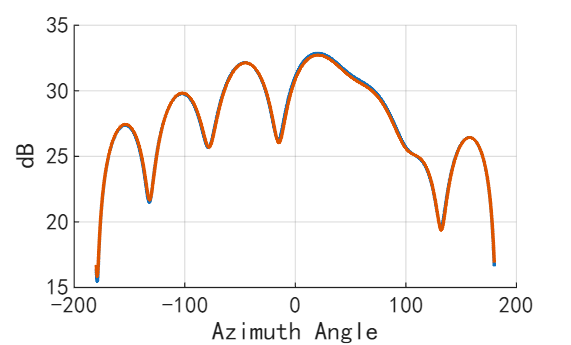


doas = zeros(K,length(ang_phi)); % direction of arrivals
figure
hold on; grid on;
for i = 1:K
    doas(i,:) = fftshift(fft(rangeFFT(cfar_ranges(i),cfar_dopps(i),:),length(ang_phi)));
    plot(ang_phi,10*log10(abs(doas(i,:))))
end
xlabel('Azimuth Angle')
ylabel('dB')

M = numCPI; % # of snapshots
% 提取所有传感器位置的x和y坐标
x_coords = cellfun(@(c) c(1), circle_loc);
y_coords = cellfun(@(c) c(2), circle_loc);
X = x_coords(:); % 转换为列向量 K×1
Y = y_coords(:); % K×1

% 生成所有角度组合(theta, phi)
num_theta = length(ang_theta);
num_phi = length(ang_phi);
[theta_grid, phi_grid] = ndgrid(ang_theta, ang_phi);
theta_list = theta_grid(:); % 列向量 M×1
phi_list = phi_grid(:);     % 列向量 M×1

% 计算角度相关的三角函数值
A_sind = sind(phi_list) .* sind(theta_list); % M×1
A_cosd = cosd(phi_list) .* sind(theta_list); % M×1

% 构造坐标矩阵和角度矩阵进行矩阵乘法
coords = [Y, X]; % K×2，列分别为Y和X坐标
A_matrix = [A_sind, A_cosd]; % M×2，列分别为sind(phi)sind(theta)和cosd(phi)sind(theta)

% 计算相位项 (矩阵乘法实现向量化)
phase = (2 * pi / lambda) * (coords * A_matrix.'); % K×M

% 计算导向矩阵
a1 = exp(-1i * phase);


music_spectrum = zeros(K, num_theta, num_phi);
[numSensors, num_angles] = size(a1);
block_size = 1000;  % 根据内存调整

for i = 1:K
    % 1. 计算协方差矩阵
    A_all = squeeze(RDMs(cfar_ranges(i), cfar_dopps(i), :, :));
    Rxx = A_all * (A_all' / M);
    
    % 2. 提取噪声子空间 (假设信号维度=1)
    [Qn, ~] = eigs(Rxx, numSensors - 1, 'smallestreal');
    Qn_H = Qn';
    
    % 3. 分块计算MUSIC谱
    spec = zeros(1, num_angles);
    for blk = 1:ceil(num_angles/block_size)
        idx = (blk-1)*block_size+1 : min(blk*block_size, num_angles);
        a1_block = a1(:, idx);
        a_proj = Qn_H * a1_block;
        spec(idx) = 1 ./ sum(abs(a_proj).^2, 1);
    end
    
    % 4. 重组为角度网格
    music_spectrum(i,:,:) = reshape(spec, [num_theta, num_phi]);
end




%% Angle Estimation - MUSIC Pseudo Spectrum
circle_loc;


M = numCPI; % # of snapshots
% a1=zeros(numRX*numTX*(2*(N_L-1)+1),length(ang_theta)*length(ang_phi));
% for k = 1:numRX*numTX*(2*(N_L-1)+1)
% 
%        for i=1:length(ang_theta)
%             for j=1:length(ang_phi)
%                 % a1(k+(l-1)*(numRX*numTX+N_L-1),i,j ...
%                 %     )=exp(-1i*2*pi*(d_y*(l-1)*cos(ang_phi(j).'*pi/180)*sin(ang_theta(i).'*pi/180) ...
%                 %     +d_tx*(k-1)*sin(ang_phi(j).'*pi/180)*sin(ang_theta(i).'*pi/180)));
%                 a1(k,i+(j-1)*length(ang_theta) ...
%                     )=exp(-1i*2*pi/lambda*(circle_loc{k}(2)*sind(ang_phi(j))*sind(ang_theta(i)) ...
%                                    +circle_loc{k}(1)*cosd(ang_phi(j))*sind(ang_theta(i)) ) );
%             end
%        end
% 
% end
% music_spectrum=zeros(K,length(ang_theta),length(ang_phi));
% for i = 1:K
%     Rxx = zeros(numRX*numTX*(2*(N_L-1)+1),numRX*numTX*(2*(N_L-1)+1));
% 
%     % A = reshape(squeeze(RDMs(:,1,:,1)),numADC,(numRX*numTX+N_L-1)*Ny);
%     % 
%     % Rxx = (A'*A);
% 
%     for m = 1:M
%        A = squeeze(RDMs(cfar_ranges(i),cfar_dopps(i),:,m));
%        Rxx = Rxx + 1/M * (A*A');
%     end
% 
%     [Q,D] = eig(Rxx); % Q: eigenvectors (columns), D: eigenvalues
%     [D, I] = sort(diag(D),'descend');
%     Q = Q(:,I); % Sort the eigenvectors to put signal eigenvectors first
%     Qs = Q(:,1); % Get the signal eigenvectors
%     Qn = Q(:,2:end); % Get the noise eigenvectors
%     for j = 1:length(ang_theta)
%         for k = 1:length(ang_phi)
%             music_spectrum(i,j,k)=(a1(:,j+(k-1)*length(ang_theta))'*a1(:,j+(k-1)*length(ang_theta)))/(a1(:,j+(k-1)*length(ang_theta))'*(Qn*Qn')*a1(:,j+(k-1)*length(ang_theta)));
%             % music_spectrum(i,j,k)=1/(a1(:,j,k)'*(Qn*Qn')*a1(:,j,k));
%         end    
%     end
% end
% a1(:,j,k)'*a1(:,j,k)
% (a1(:,j,k)'*a1(:,j,k))/(a1(:,j,k)'*(Qn*Qn')*a1(:,j,k))


%% 方位角坐标修正
% 生成修正后的方位角坐标 (自动处理-180~180循环)
ang_phi_shifted = mod(ang_phi + delta_phi +180, 360) - 180; 

%% 数据与坐标对齐
% 获取修正后坐标的排序索引（保证单调性）
[ang_phi_sorted, sort_idx] = sort(ang_phi_shifted);

% 对频谱数据按新方位角排序（沿phi轴重排）
spectrum_shifted = squeeze(music_spectrum(1,:,:)); 
spectrum_shifted = spectrum_shifted(:, sort_idx); 




figure;
% mesh(10*log10(abs(reshape(music_spectrum(1,:,:),length(ang_theta),length(ang_phi)))));
mesh(ang_phi_sorted,ang_theta,10*log10(abs(squeeze(spectrum_shifted))));
 



spectrum_data = 10 * log10(abs(reshape(spectrum_shifted, length(ang_theta), length(ang_phi_sorted))));

% 找到最大值及其索引
[max_value, max_index] = max(spectrum_data(:));
[row, col] = ind2sub(size(spectrum_data), max_index);

% 获取对应的角度
theta_max = ang_theta(row);
phi_max = ang_phi_sorted(col);

% 输出结果
fprintf('最高点坐标: (Theta: %.2f, Phi: %.2f), 强度: %.2f dB\n', theta_max, phi_max, max_value);

最高点坐标: (Theta: 29.60, Phi: 82.70), 强度: 15.61 dB


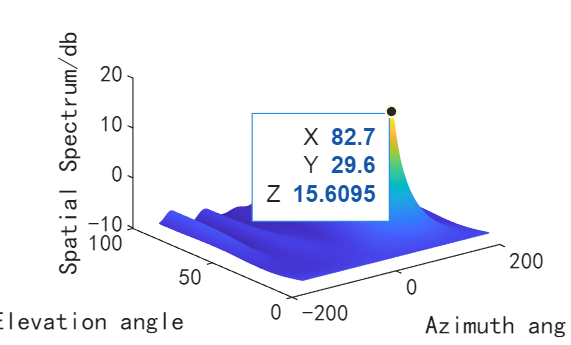

% fprintf('修正点坐标: (Theta: %.2f, Phi: %.2f), 强度: %.2f dB\n', theta_max-tar1_theta*0.1*lambda, phi_max+360/N_num/numRX, max_value);
ax = gca;
chart = ax.Children(1);
datatip(chart,phi_max,theta_max,max_value);

% xlabel('方位角');ylabel('仰角');
xlabel('Azimuth angle');ylabel('Elevation angle');
zlabel('Spatial Spectrum/db');
grid;



% % 计算3dB带宽
% threshold = max_value - 20; % 3dB对应的值
% 
% % 找到小于阈值的索引
% [x_values,y_values]= find(spectrum_data >= threshold);
% 
% % 计算带宽
% x_min = min(x_values); % 3dB下降位置的最小值
% x_max = max(x_values); % 3dB下降位置的最大值
% x_bandwidth = x_max - x_min; % 计算带宽
% 
% y_min = min(y_values); % 3dB下降位置的最小值
% y_max = max(y_values); % 3dB下降位置的最大值
% y_bandwidth = y_max - y_min; % 计算带宽
% 
% % 输出带宽
% fprintf('方位角10dB带宽为: %.2f\n', x_bandwidth);
% fprintf('仰角10dB带宽为: %.2f\n', y_bandwidth);

%% 方位角坐标修正
% 生成修正后的方位角坐标 (自动处理-180~180循环)
ang_phi_shifted = mod(ang_phi + delta_phi +180, 360) - 180; 

%% 数据与坐标对齐
% 获取修正后坐标的排序索引（保证单调性）
[ang_phi_sorted, sort_idx] = sort(ang_phi_shifted);

% 对频谱数据按新方位角排序（沿phi轴重排）
spectrum_shifted = squeeze(music_spectrum(2,:,:)); 
spectrum_shifted = spectrum_shifted(:, sort_idx); 


figure;
% mesh(10*log10(abs(reshape(music_spectrum(1,:,:),length(ang_theta),length(ang_phi)))));
mesh(ang_phi_sorted,ang_theta,10*log10(abs(squeeze(spectrum_shifted))));
 

spectrum_data = 10 * log10(abs(reshape(spectrum_shifted, length(ang_theta), length(ang_phi_sorted))));

% 找到最大值及其索引
[max_value, max_index] = max(spectrum_data(:));
[row, col] = ind2sub(size(spectrum_data), max_index);

% 获取对应的角度
theta_max = ang_theta(row);
phi_max = ang_phi_sorted(col);

% 输出结果
fprintf('最高点坐标: (Theta: %.2f, Phi: %.2f), 强度: %.2f dB\n', theta_max, phi_max, max_value);

最高点坐标: (Theta: 27.20, Phi: 83.50), 强度: 10.28 dB


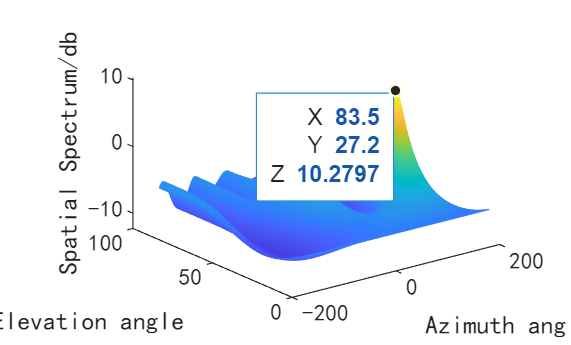


% fprintf('修正点坐标: (Theta: %.2f, Phi: %.2f), 强度: %.2f dB\n', theta_max-tar2_theta*0.1*lambda, phi_max+360/N_num/numRX, max_value);
ax = gca;
chart = ax.Children(1);
datatip(chart,phi_max,theta_max,max_value);

xlabel('Azimuth angle');ylabel('Elevation angle');
zlabel('Spatial Spectrum/db');
grid;




RDC_plus_rot_frame=RDC_plus_rot(:,1:numChirps_new,:);

M = numCPI; % # of snapshots

A = reshape(squeeze(RDC_plus_rot_frame(:,1:100,:)),numADC*100,numRX*numTX*(2*(N_L-1)+1));

Rxx = (A'*A);



[Q,D] = eig(Rxx); % Q: eigenvectors (columns), D: eigenvalues
[D, I] = sort(diag(D),'descend');
Q = Q(:,I); % Sort the eigenvectors to put signal eigenvectors first
Qs = Q(:,1); % Get the signal eigenvectors
Qn = Q(:,3:end); % Get the noise eigenvectors
% for j = 1:length(ang_theta)
%     for k = 1:length(ang_phi)
%         music_spectrum(2,j,k)=(a1(:,j+(k-1)*length(ang_theta))'*a1(:,j+(k-1)*length(ang_theta)))/(a1(:,j+(k-1)*length(ang_theta))'*(Qn*Qn')*a1(:,j+(k-1)*length(ang_theta)));
%     end
% end

% 预计算噪声空间投影矩阵
QnQn = Qn * Qn';

% 提取所有角度对应的导向矢量矩阵 (numElements x numAngles)
A_all = a1; % 维度 [numRX*numTX*(2*(N_L-1)+1), length(ang_theta)*length(ang_phi)]

% 批量计算分子：每个导向矢量的自相关 (等效||a||^2)
numerator = sum(conj(A_all) .* A_all, 1); % 结果为行向量 [1 x numAngles]

% 批量计算分母：a'*(QnQn)*a
QnQn_A = QnQn * A_all;                     % 矩阵乘法加速核心
denominator = sum(conj(A_all) .* QnQn_A, 1); % 结果为行向量 [1 x numAngles]

% 计算MUSIC谱并重塑为二维矩阵
music_spectrum_2D = reshape(numerator ./ denominator, length(ang_theta), length(ang_phi));








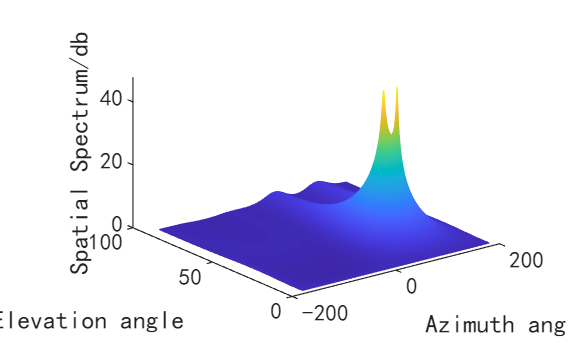



%% 方位角坐标修正
% 生成修正后的方位角坐标 (自动处理-180~180循环)
ang_phi_shifted = mod(ang_phi + delta_phi + 180+180, 360) - 180; 

%% 数据与坐标对齐
% 获取修正后坐标的排序索引（保证单调性）
[ang_phi_sorted, sort_idx] = sort(ang_phi_shifted);

% 对频谱数据按新方位角排序（沿phi轴重排）
spectrum_shifted = squeeze(music_spectrum_2D); 
spectrum_shifted = spectrum_shifted(:, sort_idx); 




figure;
mesh(ang_phi_sorted,ang_theta,10*log10(abs(squeeze(spectrum_shifted))));
 
xlabel('Azimuth angle');ylabel('Elevation angle');
zlabel('Spatial Spectrum/db');
grid;

spectrum_data = 10 * log10(abs(reshape(spectrum_shifted, length(ang_theta), length(ang_phi))));

smoothed_spectrum=spectrum_data;

% 检测区域最大值
regional_max = imregionalmax(smoothed_spectrum);

% 获取峰值位置和数值
[max_rows, max_cols] = find(regional_max);
peak_values = smoothed_spectrum(regional_max);

% 合并信息并按峰值强度降序排序
peaks_info = sortrows([max_rows, max_cols, peak_values], -3);

% 提取前两个峰值
if size(peaks_info, 1) >= 1
    main_peak = peaks_info(1, :);
    fprintf('仰角(theta)=%.2f°，方位角(phi)=%.2f°\n', ...
            ang_theta(main_peak(1)), ang_phi_sorted(main_peak(2)));
        % fprintf('修正仰角(theta)=%.2f°，方位角(phi)=%.2f°\n', ...
        %     ang_theta(main_peak(1)), mod(ang_phi_sorted(main_peak(2))+360/N_num/numRX+180, 360) - 180);
end

仰角(theta)=30.30°，方位角(phi)=95.20°



if size(peaks_info, 1) >= 2
    second_peak = peaks_info(2, :);
    fprintf('仰角(theta)=%.2f°，方位角(phi)=%.2f°\n', ...
            ang_theta(second_peak(1)), ang_phi_sorted(second_peak(2)));
        % fprintf('修正仰角(theta)=%.2f°，方位角(phi)=%.2f°\n', ...
        %     ang_theta(second_peak(1)), mod(ang_phi_sorted(second_peak(2))+360/N_num/numRX+180, 360) - 180);
else
    disp('未找到明显的次峰值。');
end

仰角(theta)=30.60°，方位角(phi)=70.40°


% DBF



% music_spectrum=zeros(K,length(ang_theta),length(ang_phi));
% 
% 
% A = reshape(squeeze(RDC_plus_rot_frame(:,1,:)),numADC*1,numRX*numTX*(2*(N_L-1)+1));
% Rxx = (A'*A);
% 
% 
% 
% % 提取所有角度对应的导向矢量矩阵 (numElements x numAngles)
% A_all = a1; % 维度 [numRX*numTX*(2*(N_L-1)+1), length(ang_theta)*length(ang_phi)]
% 
% % 批量计算分子：每个导向矢量的自相关 (等效||a||^2)
% numerator = sum(conj(A_all) .* A_all, 1); % 结果为行向量 [1 x numAngles]
% 
% % 批量计算分母：a'*(QnQn)*a 
% QnQn_A = Rxx * A_all;                     % 矩阵乘法加速核心
% denominator = sum(conj(A_all) .* QnQn_A, 1); % 结果为行向量 [1 x numAngles]
% 
% % 计算MUSIC谱并重塑为二维矩阵
% music_spectrum_2D = reshape(numerator ./ denominator, length(ang_theta), length(ang_phi));
% 
% 
% 
% 
% %% 方位角坐标修正
% % 生成修正后的方位角坐标 (自动处理-180~180循环)
% ang_phi_shifted = mod(ang_phi  + 180+180, 360) - 180; 
% 
% %% 数据与坐标对齐
% % 获取修正后坐标的排序索引（保证单调性）
% [ang_phi_sorted, sort_idx] = sort(ang_phi_shifted);
% 
% % 对频谱数据按新方位角排序（沿phi轴重排）
% spectrum_shifted = squeeze(music_spectrum_2D); 
% spectrum_shifted = spectrum_shifted(:, sort_idx); 
% 
% 
% 
% figure;
% mesh(ang_phi,ang_theta,10*log10(abs(squeeze(music_spectrum_2D))));
% 
% xlabel('方位角');ylabel('仰角');
% zlabel('空间谱/db');
% grid;
% spectrum_data = 10 * log10(abs(reshape(music_spectrum_2D, length(ang_theta), length(ang_phi))));
% 
% 
% smoothed_spectrum=spectrum_data;
% % 检测区域最大值
% regional_max = imregionalmax(smoothed_spectrum);
% 
% % 获取峰值位置和数值
% [max_rows, max_cols] = find(regional_max);
% peak_values = smoothed_spectrum(regional_max);
% 
% % 合并信息并按峰值强度降序排序
% peaks_info = sortrows([max_rows, max_cols, peak_values], -3);
% 
% % 提取前两个峰值
% if size(peaks_info, 1) >= 1
%     main_peak = peaks_info(1, :);
%     fprintf('仰角(theta)=%.2f°，方位角(phi)=%.2f°\n', ...
%             ang_theta(main_peak(1)), ang_phi(main_peak(2)));
%         fprintf('修正仰角(theta)=%.2f°，方位角(phi)=%.2f°\n', ...
%             ang_theta(main_peak(1)), ang_phi(main_peak(2)));
% end
% 
% if size(peaks_info, 1) >= 2
%     second_peak = peaks_info(2, :);
%     fprintf('仰角(theta)=%.2f°，方位角(phi)=%.2f°\n', ...
%             ang_theta(second_peak(1)), ang_phi(second_peak(2)));
%         fprintf('修正仰角(theta)=%.2f°，方位角(phi)=%.2f°\n', ...
%             ang_theta(second_peak(1)), ang_phi(second_peak(2)));
% else
%     disp('未找到明显的次峰值。');
% end



%% Point Cloud


% 
% [~, ang] = max(music_spectrum(2,:,:));
% a_phi_1 = ang_phi(ang(2));
% a_theta_1=ang_theta(ang(1));
% 
% [~, I] = max(music_spectrum(1,:));
% angle2 = ang_phi(I);
% 
% coor1 = [cfar_ranges_real(2)*sind(angle1) cfar_ranges_real(2)*cosd(angle1) 0];
% coor2 = [cfar_ranges_real(1)*sind(angle2) cfar_ranges_real(1)*cosd(angle2) 0];
% figure
% hold on;
% title('3D Coordinates (Point Cloud) of the targets')
% scatter3(coor1(1),coor1(2),coor1(3),100,'m','filled','linewidth',9)
% scatter3(coor2(1),coor2(2),coor2(3),100,'b','filled','linewidth',9)
% xlabel('Range (m) X')
% ylabel('Range (m) Y')
% zlabel('Range (m) Z')


% %% MUSIC Range-AoA map
% rangeFFT = fft(RDC_plus_rot);
% for i = 1:N_range
%     Rxx = zeros(numRX*numTX*(2*(N_L-1)+1),numRX*numTX*(2*(N_L-1)+1));
%     for m = 1:M
%        A = squeeze(sum(rangeFFT(i,(m-1)*numChirps_new+1:m*numChirps_new,:),2));
%        Rxx = Rxx + 1/M * (A*A');
%     end
% %     Rxx = Rxx + sqrt(noise_pow/2)*(randn(size(Rxx))+1j*randn(size(Rxx)));
%     [Q,D] = eig(Rxx); % Q: eigenvectors (columns), D: eigenvalues
%     [D, I] = sort(diag(D),'descend');
%     Q = Q(:,I); % Sort the eigenvectors to put signal eigenvectors first
%     Qs = Q(:,1); % Get the signal eigenvectors
%     Qn = Q(:,2:end); % Get the noise eigenvectors
% 
%     for k=1:length(ang_phi)
%         music_spectrum2(k)=(a1(:,k)'*a1(:,k))/(a1(:,k)'*(Qn*Qn')*a1(:,k));
%     end
% 
%     range_az_music(i,:) = music_spectrum2;
% end
% 
% figure
% colormap(jet)
% imagesc(ang_phi,R,20*log10(abs(range_az_music)./max(abs(range_az_music(:))))); 
% xlabel('Azimuth')
% ylabel('Range (m)')
% title('MUSIC Range-Angle Map')
% clim = get(gca,'clim');


%% Angle Estimation - Compressed Sensing

% num_phi = length(ang_phi); % divide FOV into fine grid
% 
% B = a1; % steering vector matrix or dictionary, also called basis matrix
% % P=zeros(length(ang_phi),length(ang_theta))
% 
% for i = 1:K
%     A = squeeze(RDMs(cfar_ranges(i),cfar_dopps(i),:,1));
%     cvx_begin
%         variable s(length(ang_theta)*length(ang_phi)) complex; %alphax(numTheta,1) phix(numTX*numRX,numTheta)...
% 
%         minimize(norm(s,1))
%         norm(A-B*s,2) <= 1;
%     cvx_end
%     cvx_status
%     cvx_optval
% 
%     P=reshape(s,length(ang_theta),length(ang_phi));
% 
%     figure
%     grid on;
%     mesh(ang_phi,ang_theta,10*log10(abs(P)))
%     title('Angle Estimation with Compressed Sensing')
%     xlabel('Azimuth')
%     ylabel('dB')
%     grid;
%     % 找到最大值及其索引
%     [max_value, max_index] = max(P(:));
%     [row, col] = ind2sub(size(spectrum_data), max_index);
% 
%     % 获取对应的角度
%     theta_max = ang_theta(row);
%     phi_max = ang_phi(col);
% 
%     % 输出结果
%     fprintf('最高点坐标: (Theta: %.2f, Phi: %.2f), 强度: %.2f dB\n', theta_max, phi_max+numRX*numTX*(2*(N_L-1)+1), max_value);
% 
% end

